clear all

% Constantes
lan=0.8;
w0=30;
k0=2*pi/lan;
z0=k0*(w0^2)/2;
e0=1;

% Mallado
X=-4*w0:w0/5:4*w0;
Y=-4*w0:w0/5:4*w0;
Z=-4*z0-z0/10000:z0/5:4*z0;
[x, y, z]=meshgrid(X,Y,Z);

% Funciones
w=w0*sqrt(1+(z./z0).^2);
ef=e0*(w0./w).*exp(-(x.^2+y.^2)./(w).^2)

ef = ef(:,:,1) =

    0.0369    0.0405    0.0442    0.0479    0.0518    0.0557    0.0597    0.0636    0.0674    0.0712    0.0748    0.0782    0.0814    0.0843    0.0869    0.0892    0.0911    0.0926    0.0937    0.0944    0.0946    0.0944    0.0937    0.0926    0.0911    0.0892    0.0869    0.0843    0.0814    0.0782    0.0748    0.0712    0.0674    0.0636    0.0597    0.0557    0.0518    0.0479    0.0442    0.0405    0.0369
    0.0405    0.0444    0.0484    0.0526    0.0568    0.0611    0.0654    0.0697    0.0739    0.0780    0.0820    0.0857    0.0892    0.0924    0.0953    0.0978    0.0999    0.1016    0.1028    0.1035    0.1037    0.1035    0.1028    0.1016    0.0999    0.0978    0.0953    0.0924    0.0892    0.0857    0.0820    0.0780    0.0739    0.0697    0.0654    0.0611    0.0568    0.0526    0.0484    0.0444    0.0405
    0.0442    0.0484    0.0528    0.0573    0.0620    0.0666    0.0714    0.0760    0.0806    0.0851    0.0894    0.0935    0.0973    0.1008    0.1040    0.1067

inten=abs(ef).^2

inten = inten(:,:,1) =

    0.0014    0.0016    0.0019    0.0023    0.0027    0.0031    0.0036    0.0040    0.0045    0.0051    0.0056    0.0061    0.0066    0.0071    0.0076    0.0080    0.0083    0.0086    0.0088    0.0089    0.0090    0.0089    0.0088    0.0086    0.0083    0.0080    0.0076    0.0071    0.0066    0.0061    0.0056    0.0051    0.0045    0.0040    0.0036    0.0031    0.0027    0.0023    0.0019    0.0016    0.0014
    0.0016    0.0020    0.0023    0.0028    0.0032    0.0037    0.0043    0.0049    0.0055    0.0061    0.0067    0.0073    0.0080    0.0085    0.0091    0.0096    0.0100    0.0103    0.0106    0.0107    0.0108    0.0107    0.0106    0.0103    0.0100    0.0096    0.0091    0.0085    0.0080    0.0073    0.0067    0.0061    0.0055    0.0049    0.0043    0.0037    0.0032    0.0028    0.0023    0.0020    0.0016
    0.0019    0.0023    0.0028    0.0033    0.0038    0.0044    0.0051    0.0058    0.0065    0.0072    0.0080    0.0087    0.0095    0.0102    0.0108    

filename = 'frame1.jpg'

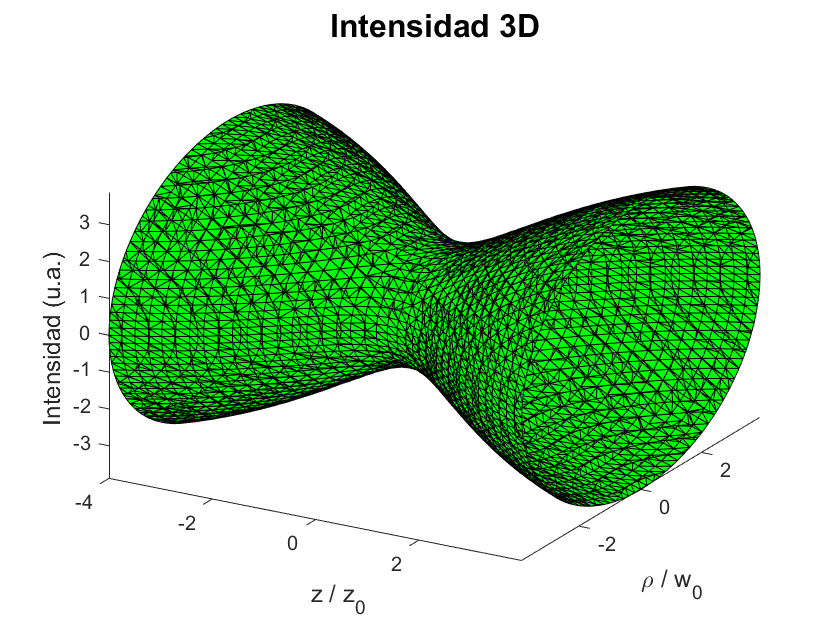

j = 1

filename = 'frame2.jpg'

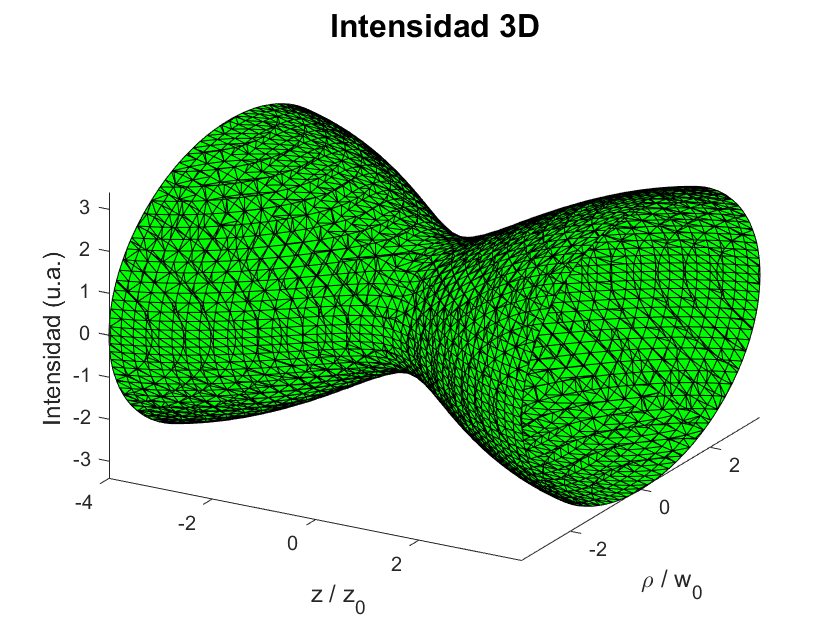

j = 2

filename = 'frame3.jpg'

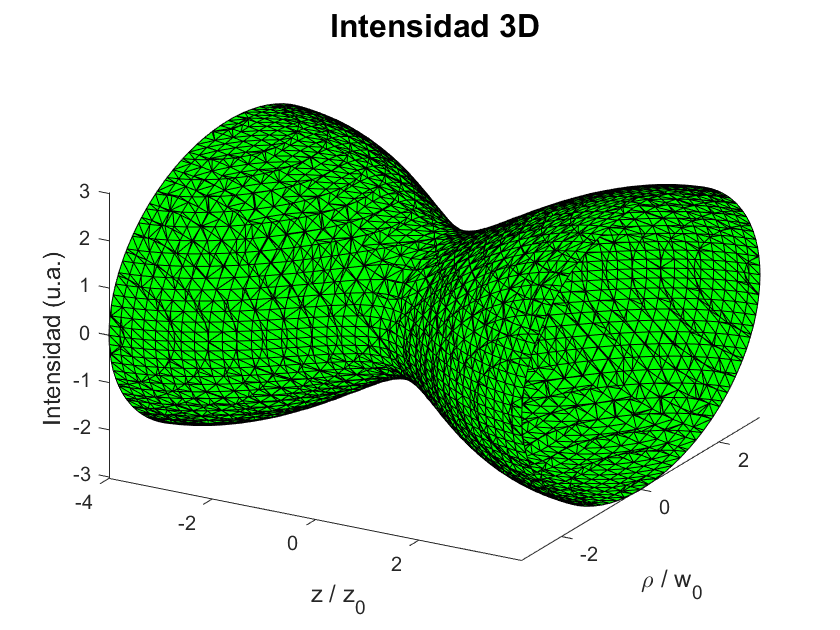

j = 3

filename = 'frame4.jpg'

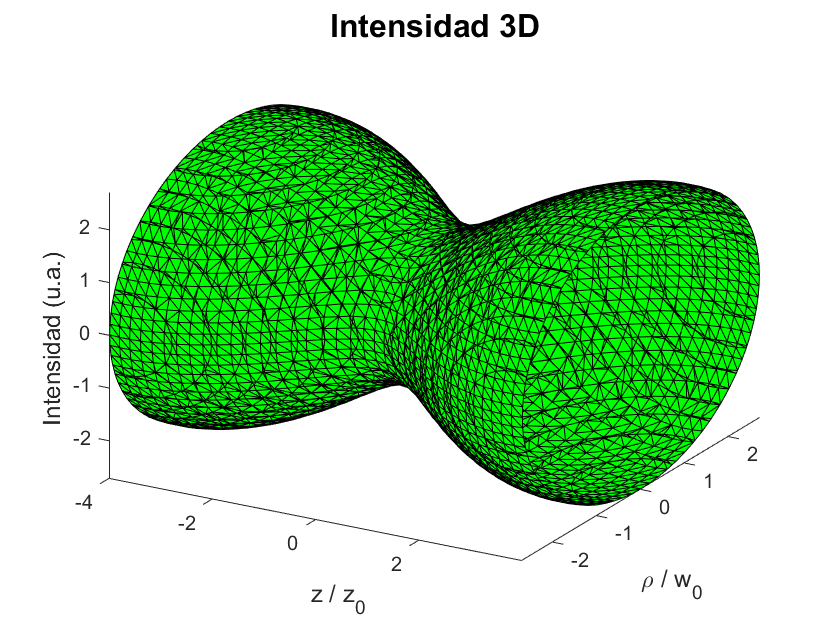

j = 4

filename = 'frame5.jpg'

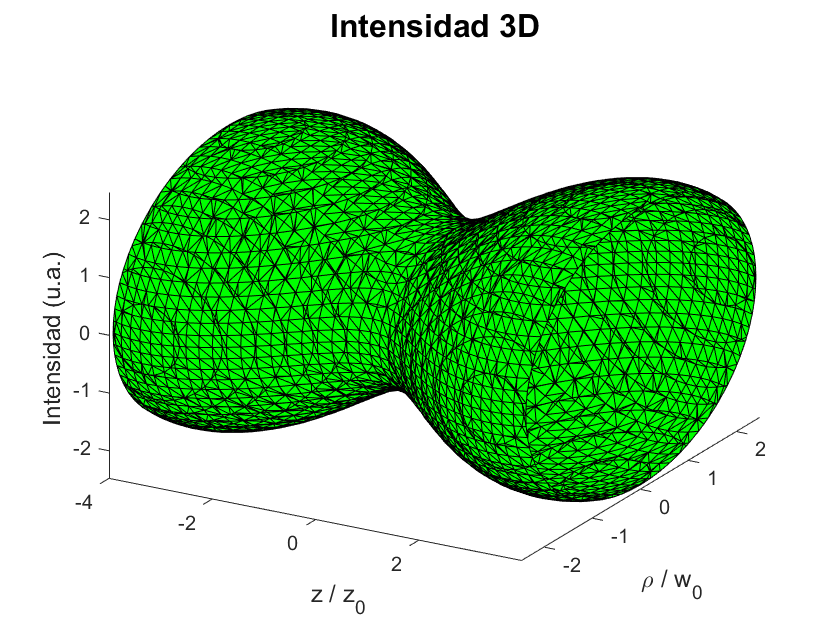

j = 5

filename = 'frame6.jpg'

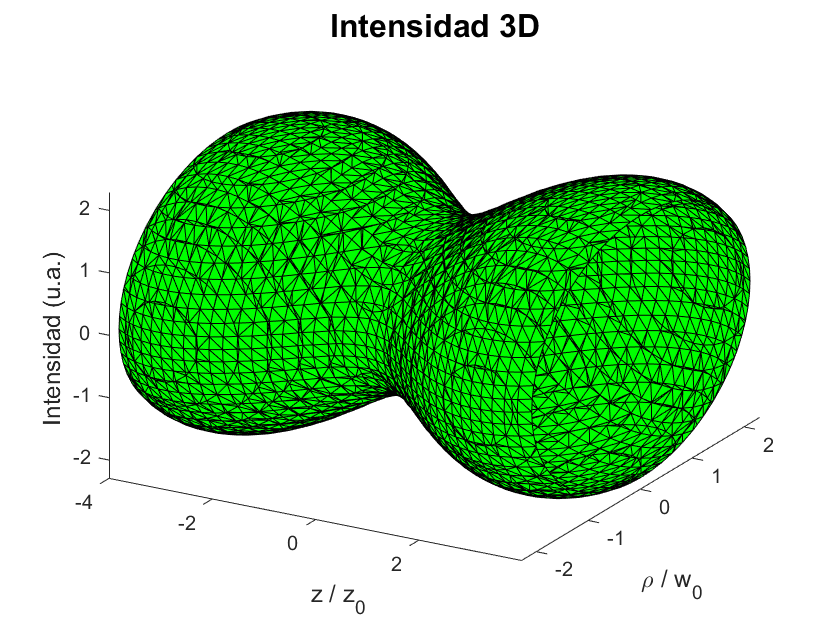

j = 6

filename = 'frame7.jpg'

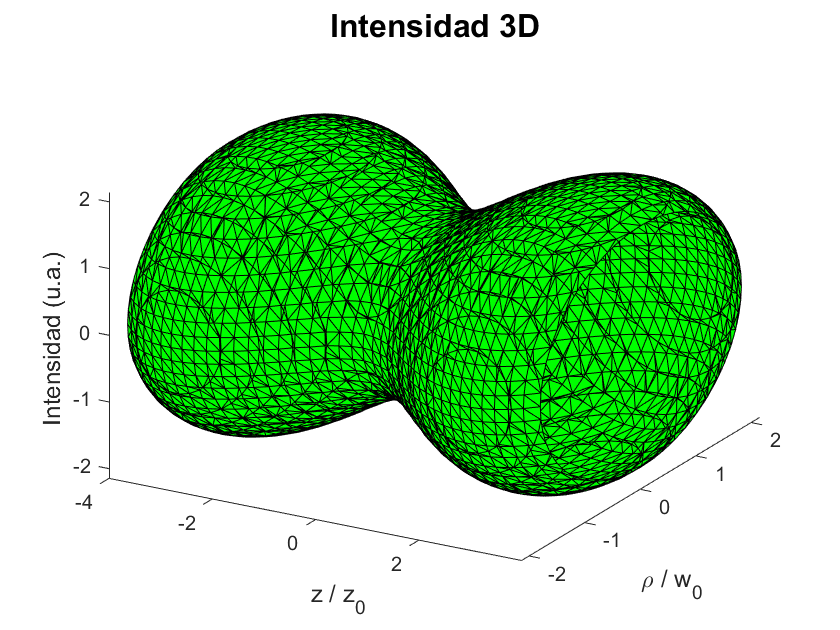

j = 7

filename = 'frame8.jpg'

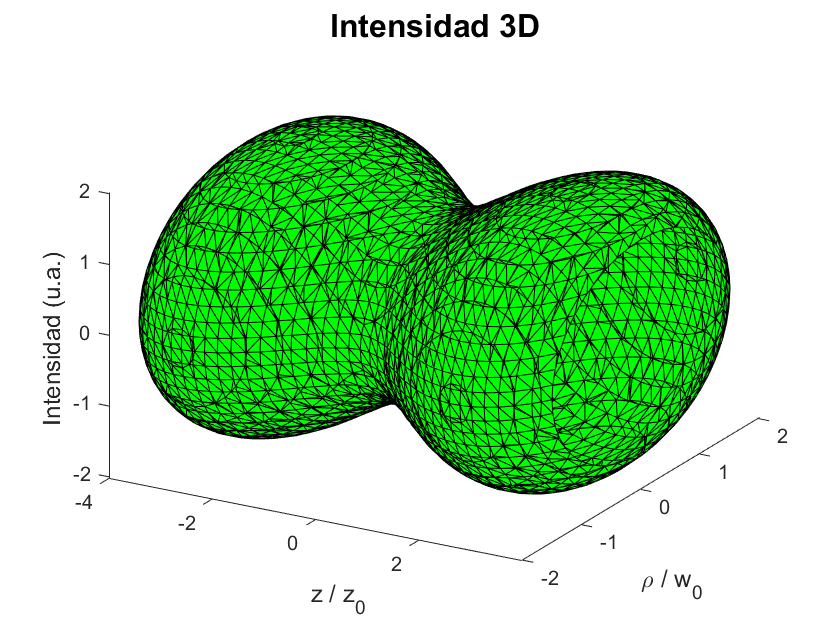

j = 8

filename = 'frame9.jpg'

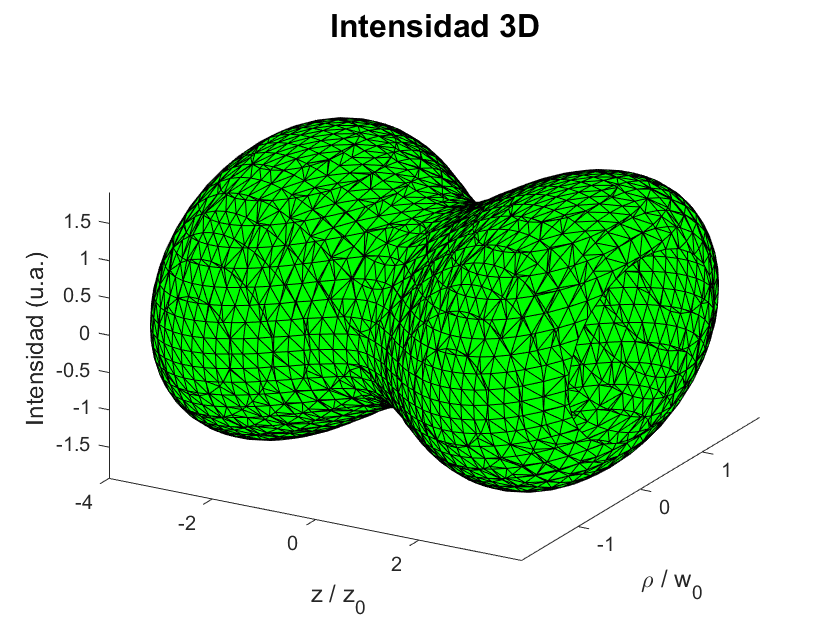

j = 9

filename = 'frame10.jpg'

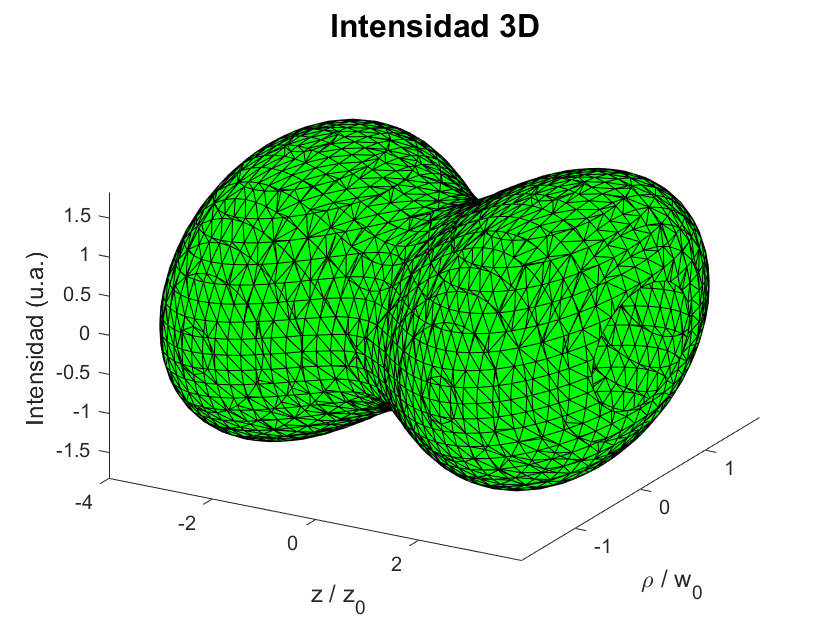

j = 10

filename = 'frame11.jpg'

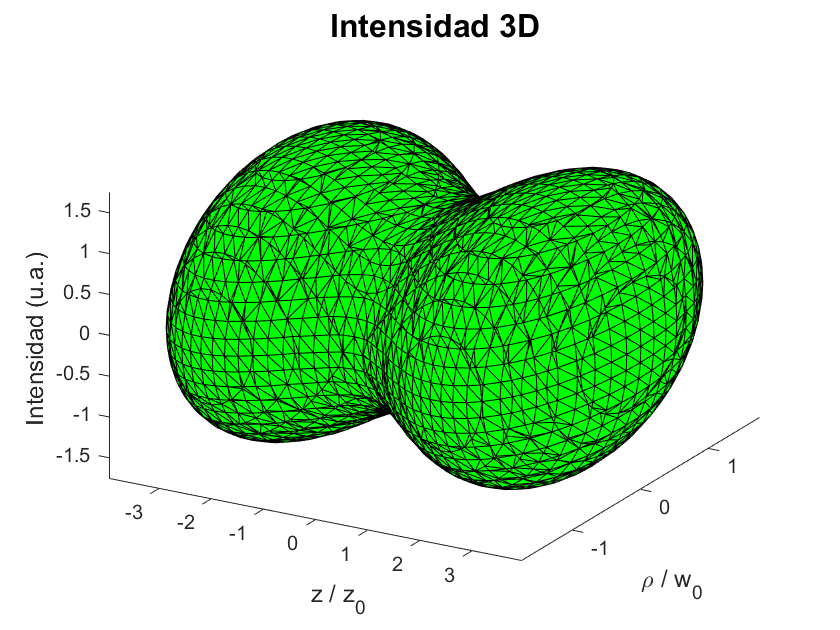

j = 11

filename = 'frame12.jpg'

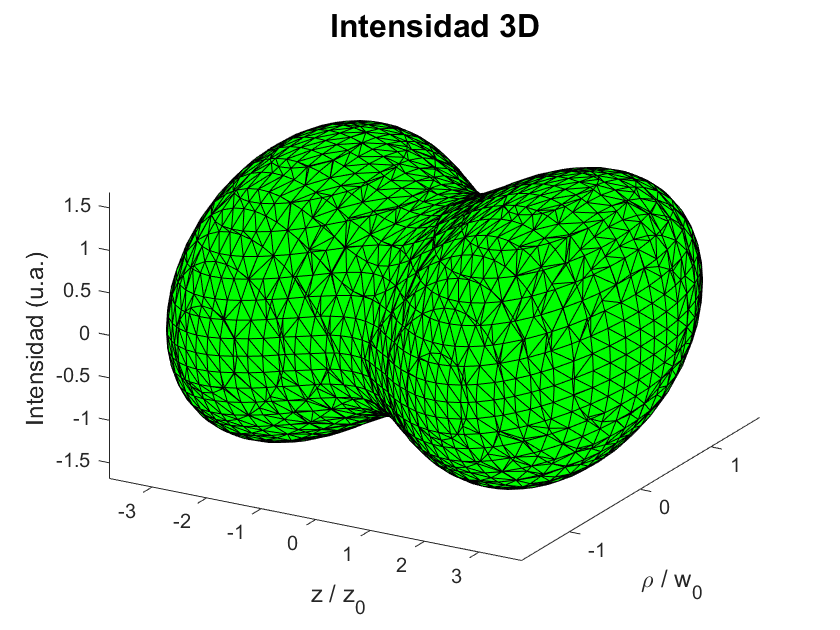

j = 12

filename = 'frame13.jpg'

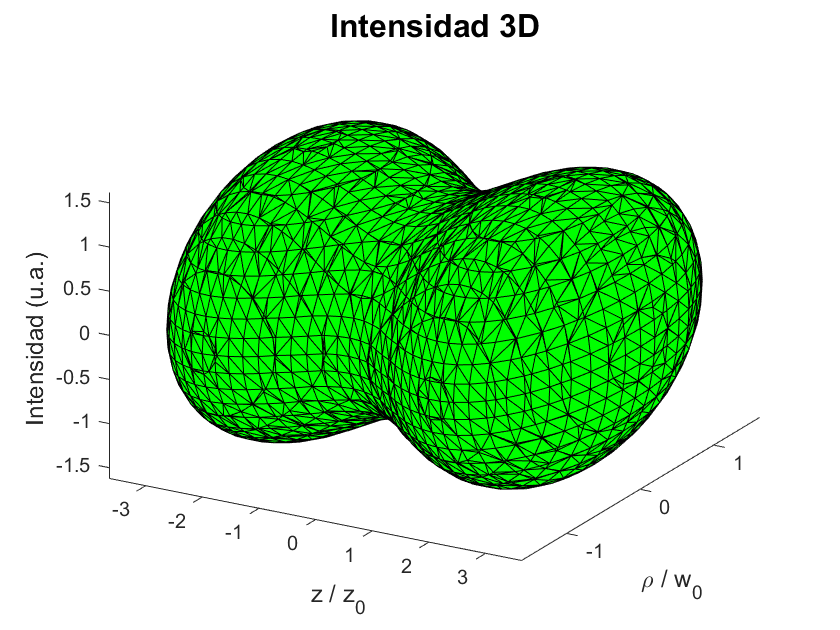

j = 13

filename = 'frame14.jpg'

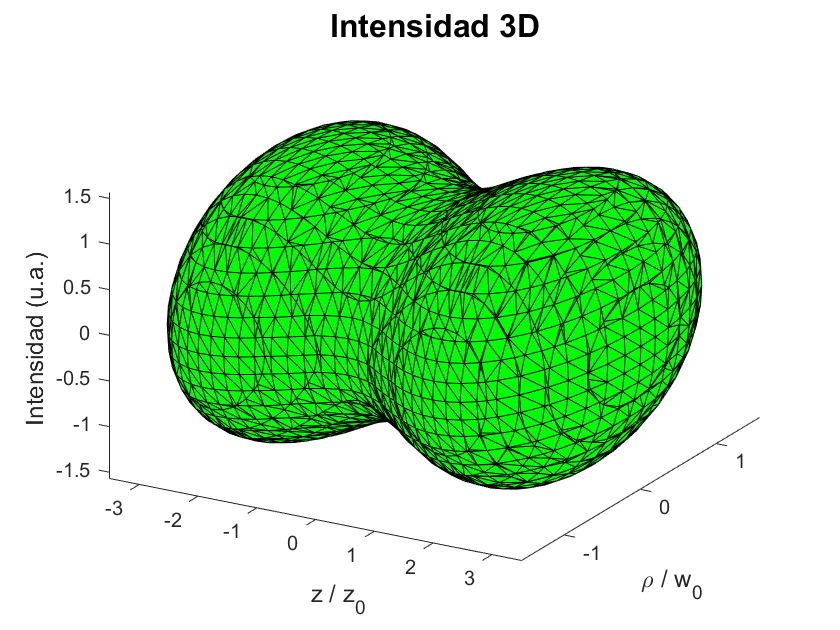

j = 14

filename = 'frame15.jpg'

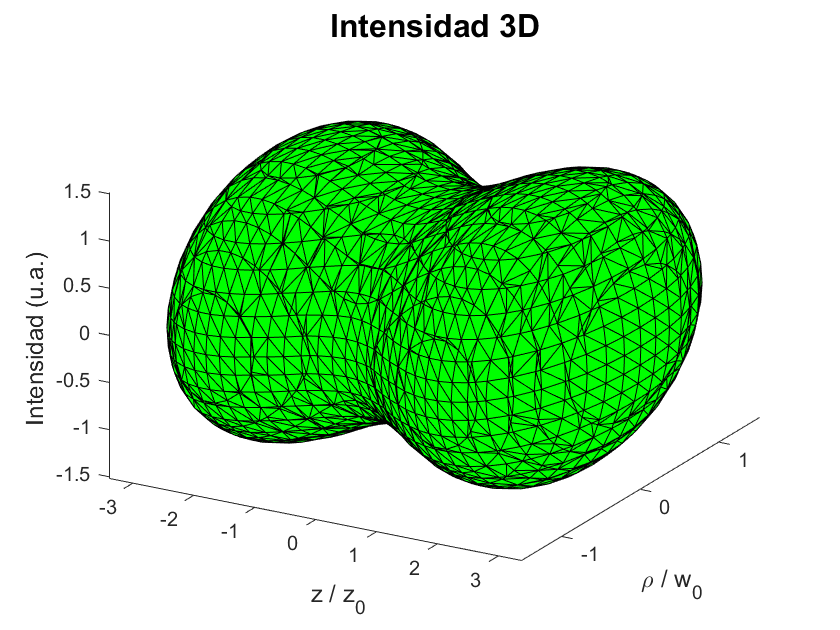

j = 15

filename = 'frame16.jpg'

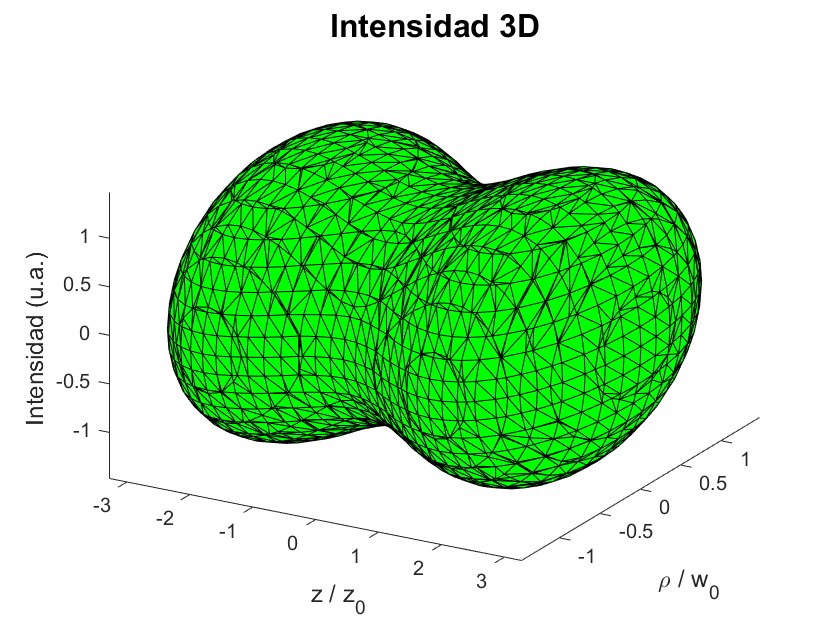

j = 16

filename = 'frame17.jpg'

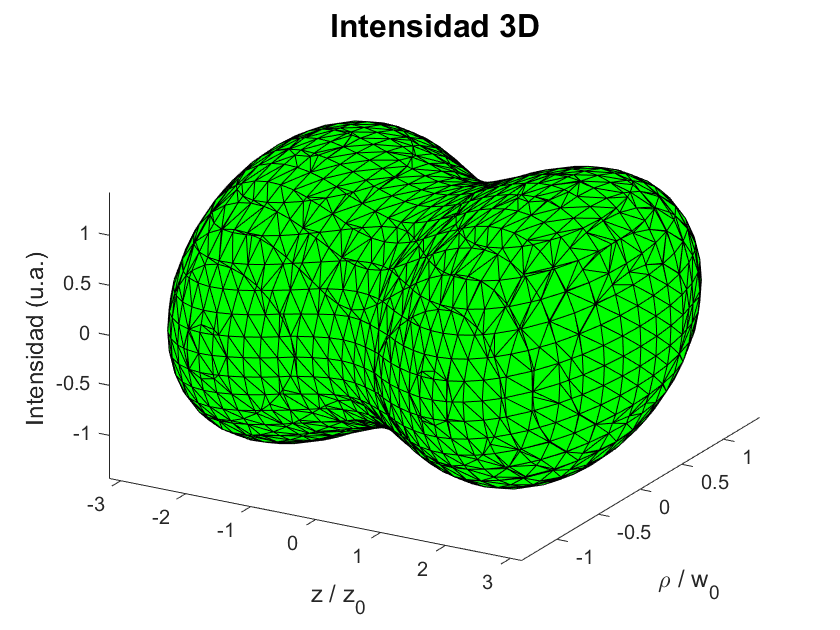

j = 17

filename = 'frame18.jpg'

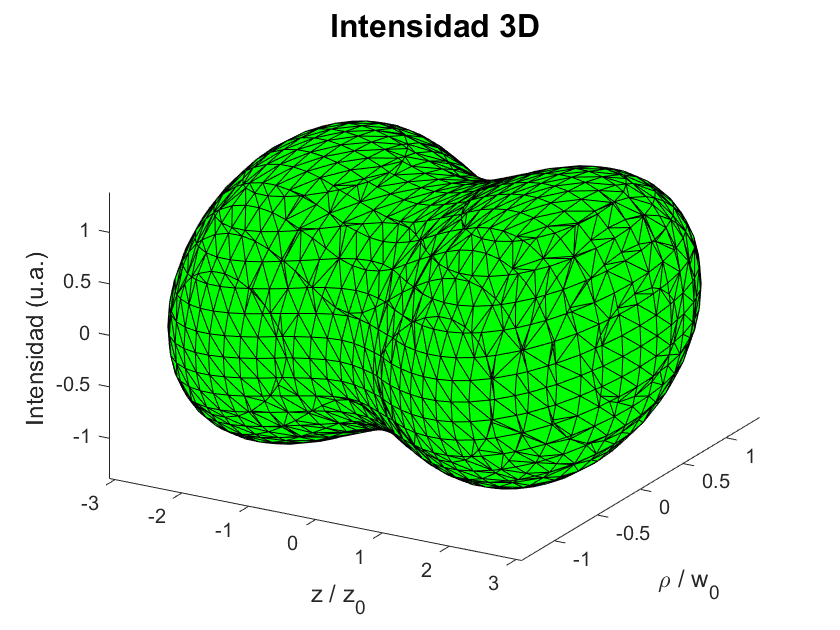

j = 18

filename = 'frame19.jpg'

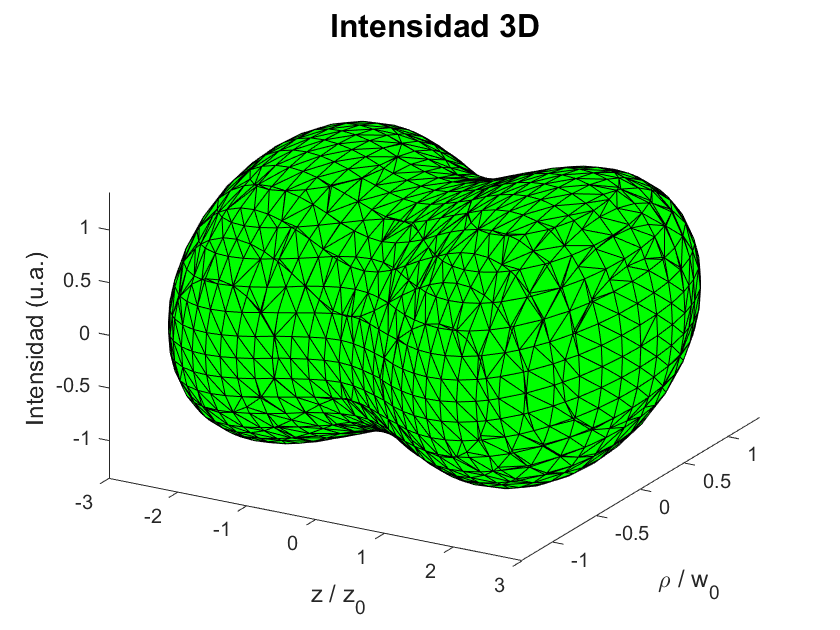

j = 19

filename = 'frame20.jpg'

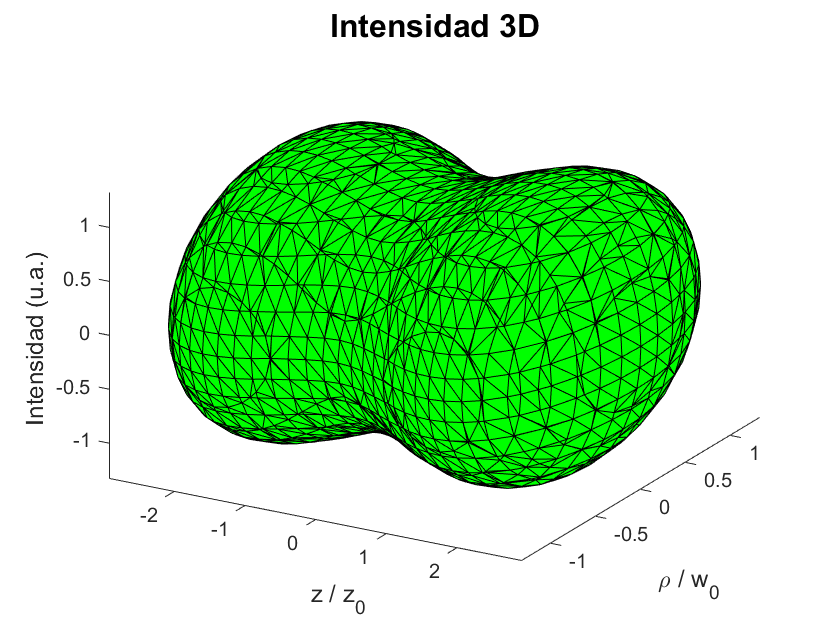

j = 20


rect = [0, 0, 540, 420];% Tamaño del frame de los videos
% Vector de la forma: [left bottom width height]

ndz=20;
Fcampo(ndz)=struct('cdata',[],'colormap',[]); % Estructura vacía 
% Cada posición del vector Fcampo almacena 'cdata' y 'colormap'
for j=1:ndz % Bucle que barre el isovalue. Cada isosurface se guarda en un frame distinto
isovalue=0.005+0.005*j;
figure
hpatch = patch(isosurface(z./z0,x./w0,y./w0,inten,isovalue));
set(hpatch,'FaceColor','green')
title('Intensidad 3D', 'FontSize', 16, 'FontName', 'Helvetica');
xlabel(' z / z_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
ylabel(' \rho / w_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
zlabel('Intensidad (u.a.) ', 'FontSize', 12, 'FontName', 'Helvetica');
view(30, 30)
axis tight
filename=sprintf('frame%d.jpg',j) % La representación se guarda como una imagen jpg
%saveas(gcf,filename); 
drawnow 
Fcampo(j) = getframe(gcf,rect); % Fcampo almacena el frame actual con el numero de pixeles de rect
%%gcf: Captura el interior de la figure window excluyendo la barra de menu y de herramientas
%imshow(Fcampo(j).cdata)
j
end


v = VideoWriter('Ej4.avi','Motion JPEG AVI');
% Creamos el archivo de video en el formato y nombre especificado
v.FrameRate=5;
v.Quality=60;
open(v); % Abrimos el video
writeVideo(v,Fcampo);
% Escribe el vector Fcampo en el archivo de video v. Fcampo almacena cada
% frame
close(v); % Cerramos el video